## MathTools HW1

%% Question 5
%2024-9-20

## Testing for n=3

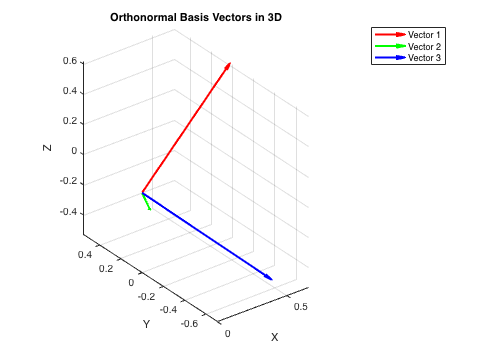

% Generate the orthonormal basis
Q4 = gramschmidt(3);

% Plot the basis vectors
figure;
quiver3(0, 0, 0, Q4(1, 1), Q4(2, 1), Q4(3, 1), 'r', 'LineWidth', 2);
hold on;
quiver3(0, 0, 0, Q4(1, 2), Q4(2, 2), Q4(3, 2), 'g', 'LineWidth', 2);
quiver3(0, 0, 0, Q4(1, 3), Q4(2, 3), Q4(3, 3), 'b', 'LineWidth', 2);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Orthonormal Basis Vectors in 3D');
legend('Vector 1', 'Vector 2', 'Vector 3');
grid on;
axis equal;
rotate3d on;
hold off;

## Verifying Orthonormality for n=1000

Reasoning: if the matrix is an orthonormal matrix, then Q4' * Q4 should be an identity matrix if the columns are orthonormal. If the rows are orthonormal, then Q4*Q4' should also be an identity matrix. 

n = 1000;
Q4b = gramschmidt(n);

% Check orthonormality of columns
orthogonality_columns = norm(Q4b' * Q4b - eye(n));

% Check orthonormality of rows
orthogonality_rows = norm(Q4b * Q4b' - eye(n));

disp(['Orthogonality of columns: ', num2str(orthogonality_columns)]);

Orthogonality of columns: 4.2513e-13


disp(['Orthogonality of rows: ', num2str(orthogonality_rows)]);

Orthogonality of rows: 4.2514e-13


To sum up, since values of *orthogonality_columns* and *orthogonality_rows *are close enought to zero, so we can say that both  Q4' * Q4 and  Q4 * Q4' are two identity matrix. Thus, the matrix is an orthonormal matrix. 

## Testing recursive function

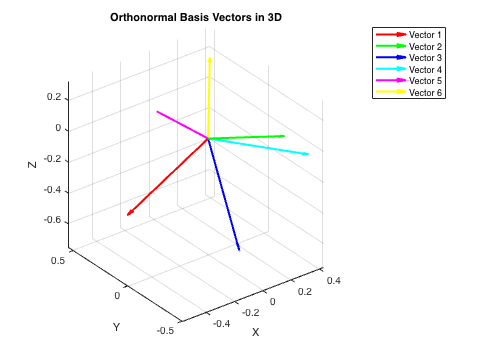

Q4_recursive = gramschmidt_recursive_main(6); 
figure;
quiver3(0, 0, 0, Q4_recursive(1, 1), Q4_recursive(2, 1), Q4_recursive(3, 1), 'r', 'LineWidth', 2);
hold on;
quiver3(0, 0, 0, Q4_recursive(1, 2), Q4_recursive(2, 2), Q4_recursive(3, 2), 'g', 'LineWidth', 2);
quiver3(0, 0, 0, Q4_recursive(1, 3), Q4_recursive(2, 3), Q4_recursive(3, 3), 'b', 'LineWidth', 2);
quiver3(0, 0, 0, Q4_recursive(1, 4), Q4_recursive(2, 4), Q4_recursive(3, 4), 'c', 'LineWidth', 2);
quiver3(0, 0, 0, Q4_recursive(1, 5), Q4_recursive(2, 5), Q4_recursive(3, 5), 'm', 'LineWidth', 2);
quiver3(0, 0, 0, Q4_recursive(1, 6), Q4_recursive(2, 6), Q4_recursive(3, 6), 'y', 'LineWidth', 2);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Orthonormal Basis Vectors in 3D');
legend('Vector 1', 'Vector 2', 'Vector 3', 'Vector 4','Vector 5','Vector 6');
grid on;
axis equal;
rotate3d on;
hold off;

function Q4 = gramschmidt(n)
Q4 = zeros(n,n); 

for i = 1:n

    %Generating a random unit vector
    unit_vector = randn(n,1);

    for j = 1:i-1
        projection = (Q4(:,j)'*unit_vector)*Q4(:,j);
        unit_vector = unit_vector - projection;
    end 

    %Normalizing teh unit vector
    unit_vector_norm = sqrt(sum(unit_vector.^2)); %getting the norm first
    Q4(:,i) = unit_vector/unit_vector_norm; 

end %for loop
end %function

%% Making a recursive 
function Q4_recursive = gramschmidt_recursive_main(n)
%a function that's calling itself
Q4_recursive = gramschmidt_recursive(n, [], 0);
end 

%the recursive part
function Q4_recursive = gramschmidt_recursive(n, Q4_previous, z)

if z == n
   Q4_recursive = Q4_previous; 
else
    %generate a random vector
    v_recursive = randn(n,1); 

    for u = 1:z
        projection_recursive = (Q4_previous(:, u)' * v_recursive) * Q4_previous(:, u);
        v_recursive = v_recursive - projection_recursive;
    end %for 

    %normalizing the vector 
    v_recursive_norm = sqrt(sum(v_recursive.^2)); %getting the norm first
    v_recursive = v_recursive/v_recursive_norm; 

    %adding a new column
    Q4_previous = [Q4_previous, v_recursive];

    %calling itself again
    Q4_recursive = gramschmidt_recursive(n, Q4_previous, z+1);

end %ifelse
end %function 